# Introduction to Tracking Metrics

While designing a multi-object tracking system, it is essential to devise a method to evaluate its performance against the available ground truth. This ground truth is typically available from a simulation environment or by using techniques like ground-truth extraction using manual or automated labeling on recorded data. Though it is possible to qualitatively evaluate a tracking algorithm using visualization tools, the approach is usually not scalable. This example introduces different quantitative analysis tools in Sensor Fusion and Tracking Toolbox™ for assessing a tracker's performance. You will also use some common events like false tracks, track swaps etc. encountered while tracking multiple objects to understand the strengths and limitations of these tools.

## Assignment and Error Metrics

The general workflow for evaluating a multi-object tracker in the presence of ground truth can be divided into 2 main steps. First, tracks are assigned to truths using an assignment algorithm. Second, using the computed assignment as an input, state-estimation accuracy for each track is computed. In each step, some key metrics for tracker's performance can be obtained. In Sensor Fusion and Tracking Toolbox™, the metrics corresponding to these two steps are termed as *assignment metrics* and *error metrics* respectively. 

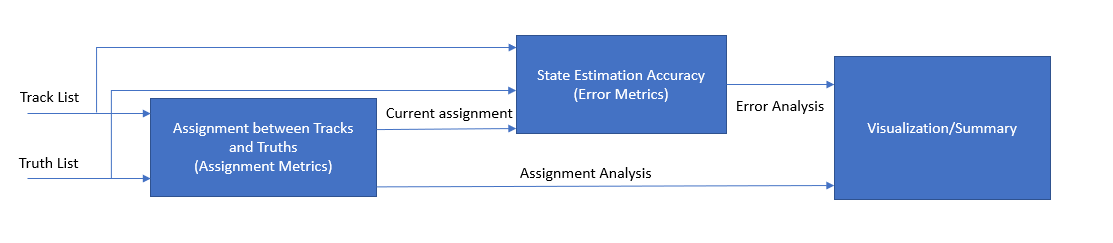

The assignment metrics assesses the characteristics of a tracker resulting due to incorrect assignment of sensor data to tracks due to ambiguity, missed targets or presence of false alarms. Incorrect assignment of sensor data can result in events like swapping of tracks between targets, creation of redundant tracks for a target, dropping of a true target track and creation of a false track. On the other hand, error metrics provide an assessment on state-estimation or object-level accuracy of the tracker. Even when a tracker does a good job at assignment, inaccuracies at track level can happen due to noise in the measurements as well as inaccuracies in modeling the target's motion model and sensor measurement model.

### Tracks and Truths Definition

The assignment metrics use a gated greedy nearest-neighbor approach which allows many-to-one track assignments, which means that multiple tracks can be assigned to the same truth. At each step, the metrics aims to assign tracks to truths while accounting for their assignment in the previous time step. This helps the assignment metrics classify tracks into certain categories based on the current as well as previous assignments. The categories used by the assignment metrics for tracks are described in the images below. 

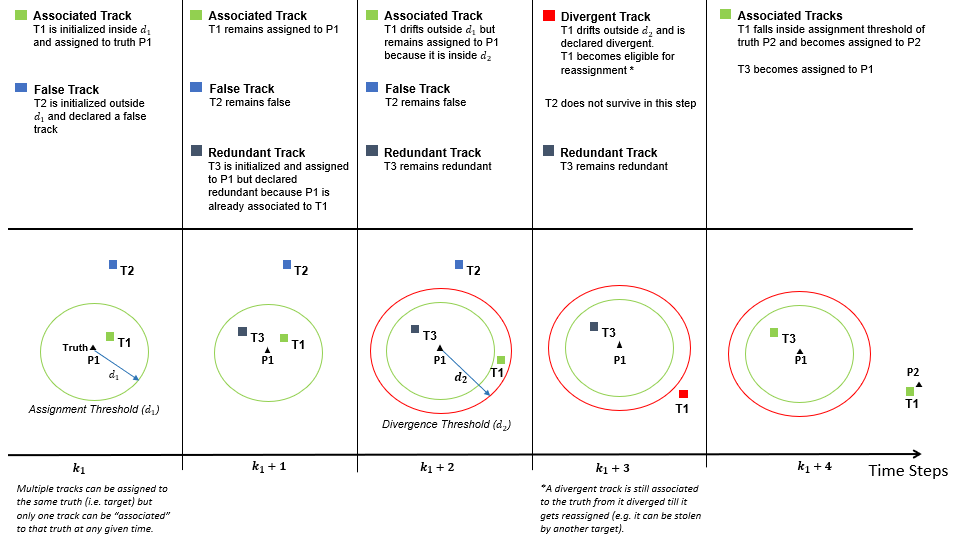

The assignments metrics also represents truths as different categories of "targets" from the tracker's perspective. This helps the assignment metrics to record events such as track establishment and target break. The establishment and break events are shown in the image below.

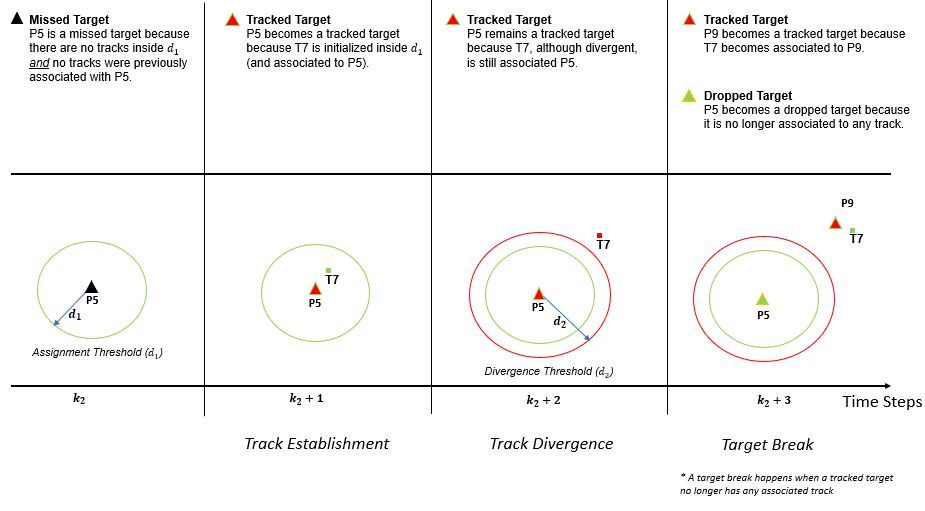

By classifying tracks and truths into multiple categories, the assignment metrics output a cumulative analysis of the tracker's performance. The metrics also provide detailed information about assignment information for each truth and track. Furthermore, the assignment results at each step from the assignment metrics can also be used to evaluate the error metrics. The error metrics output a cumulative analysis of a tracker's accuracy in state-estimation. Similar to assignment metrics, error metrics also provide detailed information for each track and truth.

Next, you will learn how to use the assignment and error metrics in MATLAB. 

### **Compute and Analyze Metrics**

To use the assignment metrics, you create the `trackAssignmentMetric` System object™. You also specify properties of the object using name-value pairs to configure the metric for different applications. In this example, you specify the assignment and divergence distance as absolute error in position between track and truth. You also specify the distance thresholds for assignment and divergence of a track.

assignmentMetrics = trackAssignmentMetrics(...
    'AssignmentDistance','posabserr',...
    'DivergenceDistance','posabserr',...
    'DivergenceThreshold',1,...
    'AssignmentThreshold',0.85)

To use the error metrics, you create the `trackErrorMetrics` System object. Since no name-value pairs are provided, the default values are used. In this example, the targets are assumed to be tracked using a constant-velocity model. 

errorMetrics = trackErrorMetrics

The assignment and error metrics are driven by simulated tracks and truths by using a helper class, `helperMetricEvaluationScenarios`. An object of this class outputs a list of tracks and truths at each time step. 

trackTruthSimulator = helperMetricEvaluationScenarios;

You also visualize the results of assignment and error metrics using a helper class named `helperMetricEvaluationDisplay`. These helper classes are included with the example in the same working folder as this script. 

display = helperMetricEvaluationDisplay(...
    'PlotTrackClassification',true,...
    'PlotTruthClassification',true,...
    'PlotTrackErrors',false,...
    'PlotTruthErrors',false,...
    'PlotAssignments',true,...
    'RecordGIF',true,...
    'ErrorToPlot','posRMS');

You generate the list of tracks and truths at each time and run the assignment and error metrics using the following workflow. 

% Time stamps at which the metrics are updated
timeStamps = 0:0.1:10;
n = numel(timeStamps);

% Initialization of recorded variables
posRMSE = zeros(n,1);
velRMSE = zeros(n,1);
posANEES = zeros(n,1);
velANEES = zeros(n,1);
truthError = cell(n,1);
trackError = cell(n,1);

% Loop over time stamps
for i = 1 : n
    % Current time
    time = timeStamps(i);
    
    % Generate tracks and truths using simulation
    [tracks, truths] = trackTruthSimulator(time);
    
    % You provide the tracks and truths as input to the assignment metrics.
    % This outputs a cumulative summary from all the tracks and the truths.
    [trackAssignmentSummary(i), truthAssignmentSummary(i)] = assignmentMetrics(tracks, truths); %#ok<SAGROW> 
    
    % For detailed assignment information about each track, you use the
    % trackMetricsTable method.
    trackTable = trackMetricsTable(assignmentMetrics);
    
    % Similarly, for detailed assignment information about each truth, you
    % use the truthMetricsTable method.
    truthTable = truthMetricsTable(assignmentMetrics);
    
    % For running error metrics, you obtain the current assignment of
    % tracks to truths using the currentAssignment method.
    [assignedTrackIDs, assignedTruthIDs] = currentAssignment(assignmentMetrics);
    
    % The current assignment information as well as the list of tracks and
    % truths at the current time can then be passed as an input to the
    % error metrics.
    [posRMSE(i),velRMSE(i),posANEES(i),velANEES(i)] = errorMetrics(tracks, assignedTrackIDs, truths, assignedTruthIDs);
    
    % For detailed error information about each record truth and track, you
    % use the cumulative metric methods on the error metrics.
    trackError{i} = cumulativeTrackMetrics(errorMetrics);
    truthError{i} = cumulativeTruthMetrics(errorMetrics);
    
    display(tracks, truths, assignedTrackIDs, assignedTruthIDs, trackTable, truthTable);
end

**Analyze Assignment Metrics**

The animation below shows a visual representation of the assignment metrics.  In the beginning, both P1 and P2 did not have any associated tracks due to establishment delay. Therefore, they were both categorized as missed targets. Around X = 5 meters, P1 was not tracked for a few time steps. Notice that the assignment metrics outputs P2 as a dropped target during this time. When the tracks swapped between P1 and P2, they were initially declared divergent as they moved out of divergence thresholds. After a few time steps, the tracks reached assignment gate of new truths and became associated to the new truth.

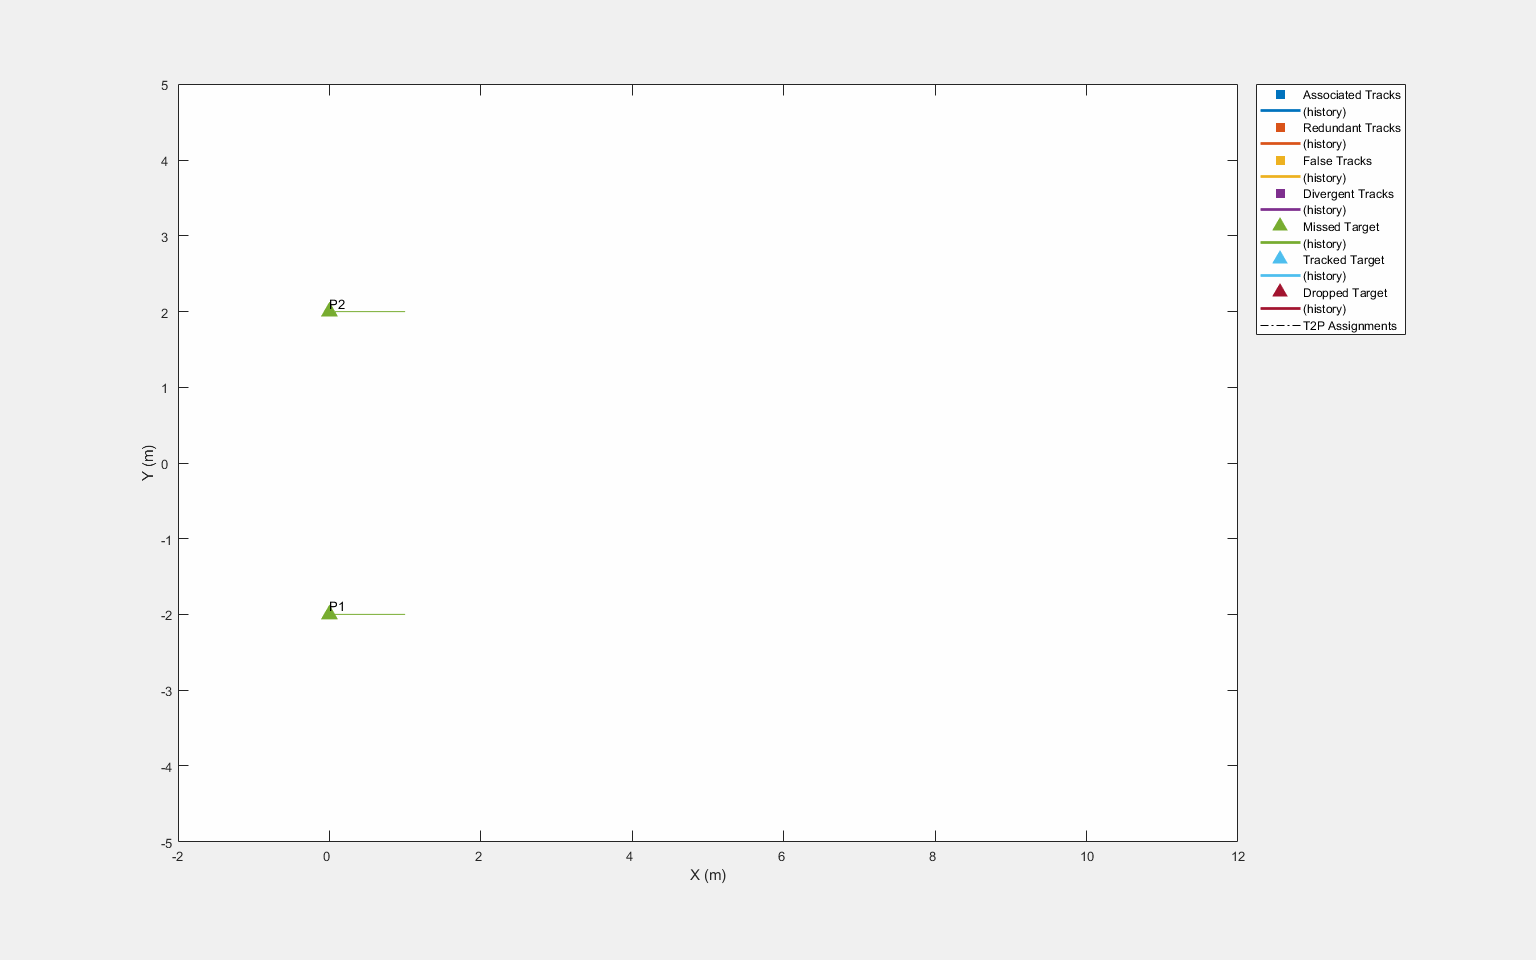

The visualization of the metric for each track and truth can help in easier understanding of different events. However, it can become overwhelming for large number of tracks and truths. An alternate approach is to use the summarized output of the assignment metrics. These outputs provide an overall summary of the assignment metrics up to the current time step. The fields and values of the assignment metrics summary at end of the simulation is shown below.

disp(trackAssignmentSummary(end));

disp(truthAssignmentSummary(end));

By capturing the assignment summary at each step, you can also plot the cumulative analysis. The following plots show a subset of the fields for both track and truth assignment summary. 

helperPlotStructArray(display,trackAssignmentSummary);
helperPlotStructArray(display,truthAssignmentSummary);

**Analyze Error Metrics**

Similar to assignment metrics, the error metrics can also be computed and visualized per track and truth. The fields of the estimation error for each track and truth at the end of simulation are shown below. Each of these fields represent the cumulative error over each track and truth. 

Estimation error for each track

disp(trackError{end});

Estimation error for each truth

disp(truthError{end});

By recording the errors at each time-step, you can also plot error vs time for each track and truth. The following plots show the RMS error in position for each track and truth. After a track is deleted, the error in its estimate remains constant. Notice that in the first-half of the simulation, the error in estimate of T3 is higher than that of T4 because the trajectory of T3 did not match the trajectory of P2 perfectly. Also notice the drop in error for estimate of T3 in the first-half as it slowly converged to the true position. During the track-swap event. the error in estimate of both T3 and T4 increased till their assignments switched.

% A utility to plot the table array. 'posRMS' is the field to plot
helperPlotTableArray(display,trackError,'posRMS');

The error in estimate of each truth is simply the cumulation of estimation error of all tracks *assigned* to it. When P2 was assigned a redundant track around 8th time-step of the simulation, its estimation error jumped. As the redundant track approached P2, the error decreases, but again increases when its associated track diverged. 

helperPlotTableArray(display,truthError,'posRMS');

For a large number of tracks and truths, you can also use cumulative error metrics for *all* assigned tracks during their life-cycle. Notice the increase in error when the tracks swapped (near the 80th step). Also notice the smaller peak around the 25th time step when T1 diverted from its assigned truth P2 and was overtaken by the redundant track T3.

f = figure('Units','normalized','Position',[0.1 0.1 0.6 0.6]);
ax = axes(f);

subplot(2,2,1)
plot(posRMSE,'LineWidth',2);
xlabel('Time step');
ylabel('RMS Error in Position (m)');
grid('on');

subplot(2,2,2)
plot(velRMSE,'LineWidth',2);
xlabel('Time step');
ylabel('RMS Error in Velocity (m/s)');
grid('on');

subplot(2,2,3)
plot(posANEES,'LineWidth',2);
xlabel('Time step');
ylabel('Average Normalized Error in Position');
grid('on');

subplot(2,2,4)
plot(velANEES,'LineWidth',2);
xlabel('Time step');
ylabel('Average Normalized Error in Velocity');
grid('on');

sgtitle('Cumulative errors for all tracks','FontWeight','bold');

## Summarizing Metrics as Scores

A common use-case for evaluating the performance of a multi-object tracker is to tune its parameters. This is typically done by combining the metrics into a single cost value that can serve as a function for an optimization algorithm. The assignment and error metrics provide several different measures of effectiveness (MoEs) and can be combined by first choosing the most relevant metrics and then performing a weighted combination depending on the application. The selection of the correct MoEs as well as their combination into a single score can be challenging. As an alternative to this approach, you can use the Optimal SubPattern Assignment (OSPA) [1] metric and Generalized Optimal SubPattern Assignment (GOSPA) [2] metric. Both OSPA and GOSPA metric assess the performance of a multi-object tracker by combining both assignment as well as state-estimation accuracy into a single cost value. Next, you will learn about OSPA and GOSPA metric and the workflow to compute these metrics in MATLAB.

### OSPA Metric

The OSPA metric can be considered as a statistical distance between multiple tracks and truths. To compute the OSPA metric, the algorithm first assigns existing tracks and truths to each other using a Global Nearest Neighbor (GNN) algorithm. Once the assignment is computed, the metric divides the overall distance into two sub-components - localization and cardinality-mismatch. The localization component captures the errors resulting from state-estimation accuracy, while the cardinality-mismatch component captures the effect of redundant tracks, false tracks and missed truths. The traditional OSPA metric does not take into account the temporal history of tracks i.e. the assignments from previous step do not affect the metric at the current step. Therefore, effects like track-switches are not captured in the traditional OSPA metric. To circumvent this, a new sub-component was introduced for OSPA called the "labeling" component [3]. Combination of traditional OSPA with "labeling" component is sometimes referred to as "OSPA for Tracks" (OSPA-T) or Labelled-OSPA (LOSPA) [4].

To use the OSPA metric in MATLAB, you use the `trackOSPAMetric `System object. You can switch from OSPA to Labelled-OSPA by providing a non-zero valued `LabelingError` property. To understand how each sub-component is calculated, refer to the "Algorithms" section of [trackOSPAMetric](docid:fusion_ref#mw_5889038b-d92d-4839-81d3-8bc2ebeb1eb3)`.`

ospaMetric = trackOSPAMetric('Distance','posabserr',...
    'CutoffDistance',1,...
    'LabelingError',0.25);

Next you run the same scenario and compute the OSPA metric at each time step.

timeStamps = 0:0.1:10;
n = numel(timeStamps);

% Scene simulation
trackTruthSimulator = helperMetricEvaluationScenarios;

% Initialize variables
ospa = zeros(n,1);
locComponent = zeros(n,1);
cardComponent = zeros(n,1);
labelingComponent = zeros(n,1);

% Loop over time stamps
for i = 1:numel(timeStamps)
    time = timeStamps(i);
    
    % Track and truth
    [tracks, truths] = trackTruthSimulator(time);
    
    % Call the System object as a function and record OSPA and all 3 components
    [ospa(i),locComponent(i),cardComponent(i),labelingComponent(i)] = ospaMetric(tracks, truths);
end

**Analyze OSPA Metric**

figure('Units','normalized','Position',[0.1 0.1 0.6 0.6]);

subplot(2,1,1);
plot(ospa,'LineWidth',2);
xlabel('Time step');
ylabel('Cost');
title('OSPA');
grid('on');

subplot(2,1,2);
plot([locComponent cardComponent labelingComponent],'LineWidth',2);
xlabel('Time step');
ylabel('Component Cost');
title('OSPA Components');
legend('Localization','Cardinality-mismatch','Labeling');
grid('on');

Notice the correlation between OSPA metric and different events in the scenario. The OSPA is high initially because of establishment delay. After establishment, the OSPA stays still relatively high due to the presence of a redundant track. After the redundant track was deleted, the OSPA dropped to a lower value. Around 50th time step the OSPA gained value as truth P1 was dropped. Notice that while the OSPA metric captures all these events correctly by providing a higher value, it does not provide finer details about each truth and track and the accuracy in their estimate. The only information available from OSPA is via its components. A higher localization component indicates that the assigned tracks do not estimate the state of the truths correctly. This localization component is computed using the same type of distance as the assignment. A higher cardinality component indicates the presence of missed targets and false or redundant tracks. A higher labeling error indicates that the tracks are not labelled correctly, which indicates that the tracks are associated to their closest available truths. 

### GOSPA Metric

The approach used to compute GOSPA is similar to OSPA metric. Using a slightly different mathematical formulation, the GOSPA metric additionally computes subcomponents such as "missed targets component" and "false tracks component". Similar to traditional OSPA, the GOSPA also does not take into account temporal history of tracks. However, a  metric similar to Labelled-OSPA can be achieved by adding a switching component [5]. The switching component captures the effect of switching assignments between truths. Each assignment change for the truth is penalized after being categorized as half-switch or full-switch. A half-switch refers to the event when a truth switches assignment from a track to being unassigned or vice-versa. A full-switch refers to the event when a truth switches assignment from one track to another.

To use the GOSPA metric in MATLAB, you create the [trackGOSPAMetric](docid:fusion_ref#sysobj_track_GOSPA_metric) System object. To account for track-switching, you provide a positive value for `SwitchingPenalty`.

gospaMetric = trackGOSPAMetric('Distance','posabserr',...
    'CutoffDistance',1,...
    'SwitchingPenalty',0.25);

Next you run the same scenario and compute the GOSPA metric at each time step.

timeStamps = 0:0.1:10;
n = numel(timeStamps);
trackTruthSimulator = helperMetricEvaluationScenarios;

% Initialize variables
labeledGospa = zeros(n,1);
traditionalGospa = zeros(n,1);
locComponent = zeros(n,1);
missedTargetComponent = zeros(n,1);
falseTrackComponent = zeros(n,1);
switchingComponent = zeros(n,1);

% Loop over time stamps
for i = 1:numel(timeStamps)
    time = timeStamps(i);
    
    % Track and truth
    [tracks, truths] = trackTruthSimulator(time);
    
    % Call the System object as a function and get all 4 components
    [labeledGospa(i),traditionalGospa(i),switchingComponent(i),locComponent(i),missedTargetComponent(i),falseTrackComponent(i)] = gospaMetric(tracks, truths);
end

**Analyze Results**

figure('Units','normalized','Position',[0.1 0.1 0.6 0.6]);

subplot(2,1,1);
plot(labeledGospa,'LineWidth',2);
xlabel('Time step');
ylabel('Cost');
title('GOSPA');
grid('on');

subplot(2,1,2);
plot([locComponent missedTargetComponent falseTrackComponent switchingComponent],'LineWidth',2);
xlabel('Time step');
ylabel('Component Cost');
title('GOSPA Components');
legend('Localization','Missed Target','False Track','Switching');
grid('on');

Notice that the GOSPA metric also captures the effect of different events during the scenario similar to the OSPA metric. In contrast to OSPA, it also provides information if the metric is higher due to false tracks or missed targets. Notice the peak is missed target component around 50th time step. This peak denotes the event when P1 was missed for a few steps. The peak around 80th time-step in missed target component denotes the event when the tracks swapped. The delay between divergence and reassignment resulted in missed targets as well as a false track components. 

The peaks in the track switching component denote different events. The first peak accounts for truths switching from unassigned to assigned. The second peak accounts for the switching of tracks on P2. The third and fourth peak captures that truth P1 was unassigned and then assigned to another track respectively. The last two peaks account for truth unassignment and then reassignment. 

Similar to OSPA, GOSPA also does not provide detailed information about each track and truth. The information from GOSPA is available via its components. As the name states, a higher missed target component denotes that targets are not being tracked and a higher false track component denotes the presence of false tracks. A higher switching penalty denotes events like establishment, track swaps and dropped tracks. The subdivision of components to include missed targets and false tracks assists in modifying the correct parameter of the tracker. For example, if false tracks are being created, a typical solution is to try and increase the threshold for track-confirmation.

## Summary

In this example you learned about three different tools to analyze the performance of a multi-object tracking system. You also learned about the workflow in MATLAB to use these metrics. You also leaned about the type of information they provide and how it can be analyzed. The tools described in this example are flexible and can be customized for different applications and use-cases. There are "built-in" options available on all the tools to specify a different types of distances to be used for the metric. For example, absolute error in position or velocity or normalized error in position or velocity. You can also specify three different motion models for the tracks: constant velocity, constant turn-rate and constant acceleration. These "built-in" functionalities support tracks in form of `objectTrack` and truths generated by scenario simulations using `trackingScenario`. If the format of tracks and truths for your application is different, you can pre-process them to convert them. This allows you to use all the "built-in" functionality of the metrics. Alternatively, you can specify a custom distance function between a track and a truth. This allows you to control the distance as well as the format of each track and truth. To switch between custom and built-in functionality for OSPA and GOSPA metric, specify the `Distance` as 'c`ustom`'. To switch between custom and built-in functionality for assignment and error metrics, change the `DistanceFunctionFormat` and `ErrorFunctionFormat` to '`custom`' for assignment and error metrics respectively.

## References

[1] Schuhmacher, Dominic, Ba-Tuong Vo, and Ba-Ngu Vo. "A consistent metric for performance evaluation of multi-object filters." *IEEE transactions on signal processing* 56.8 (2008): 3447-3457.

[2] Rahmathullah, Abu Sajana, Ángel F. García-Fernández, and Lennart Svensson. "Generalized optimal sub-pattern assignment metric." *2017 20th International Conference on Information Fusion (Fusion)*. IEEE, 2017.

[3] Ristic, Branko, et al. "A metric for performance evaluation of multi-target tracking algorithms." *IEEE Transactions on Signal Processing* 59.7 (2011): 3452-3457.

[4] Mahler, Ronald PS. *Advances in statistical multisource-multitarget information fusion*. Artech House, 2014.

[5] Garcia-Fernandez, Angel F., et al. “A Metric on the Space of Finite Sets of Trajectories for Evaluation of Multi-Target Tracking Algorithms.” *IEEE Transactions on Signal Processing*, vol. 68, 2020, pp. 3917–28.

Copyright 2019 The MathWorks, Inc.